# Polynomial Regression

We will demonstrate the effect of the degree of the polynomial model on the fit of the data. For high degree, the polynomial is very flexible and can fit the data well, but the polynomial may vary wildly in between data points. For low degree, the polynomial is not very flexible and will be quite smooth. This example illustrates the important concept of *overfitting* in machine learning.

First generate some synthetic data.

fun = @(x) sin(2*pi*x); % true function
sigma2 = 0.1;           % noise variance
n = 10;                 % number of observations
delta = 1/(n+1);        % spacing between observations
x = (delta:delta:1-delta)';
y = fun(x) + sqrt(sigma2)*randn(size(x));

Set up the least squares design matrix for polynomials up to degree 9.

X0 = [ones(n,1) x x.^2 x.^3 x.^4 x.^5 x.^6 x.^7 x.^8 x.^9];

Loop over the polynomial degree and compute and plot the polynomial model.

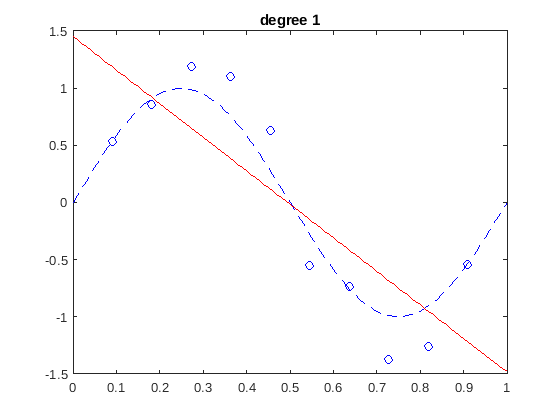

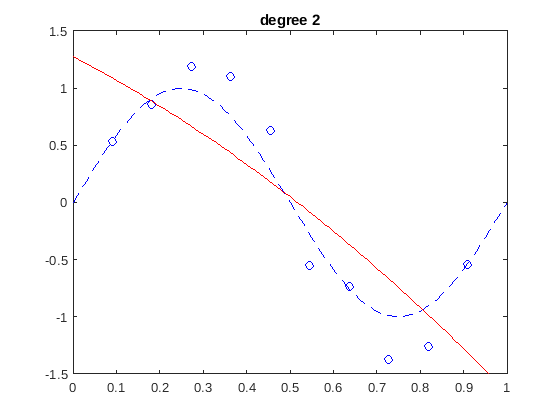

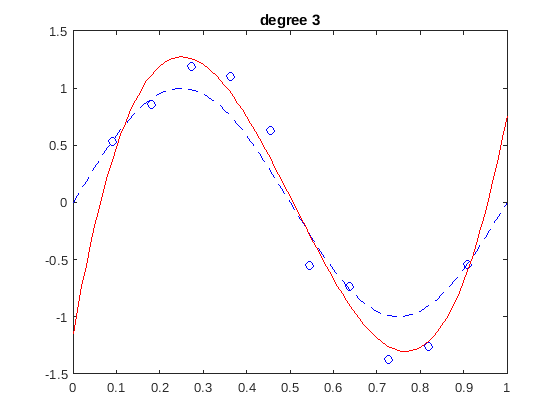

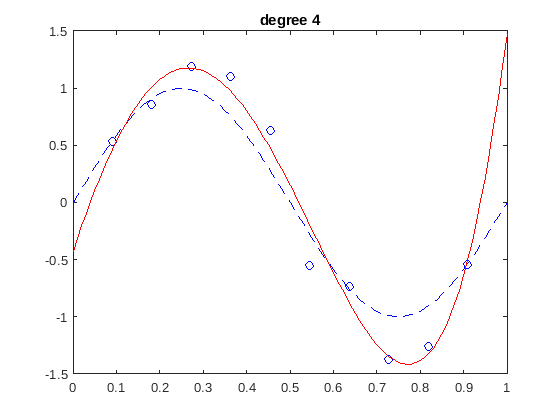

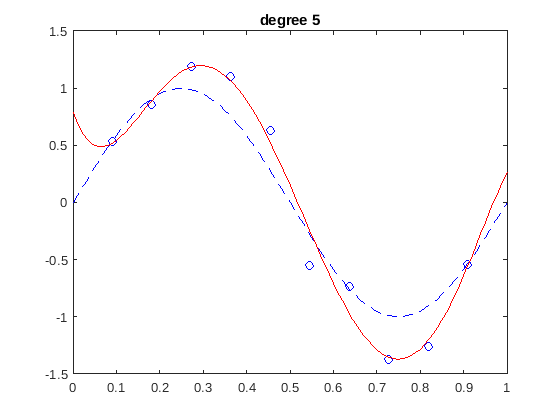

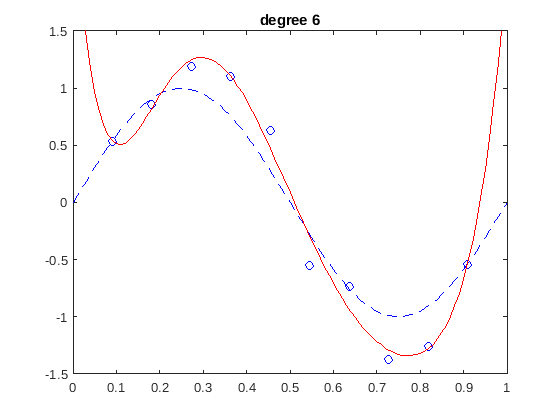

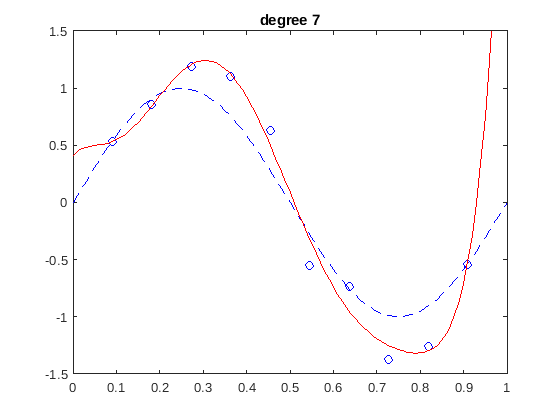

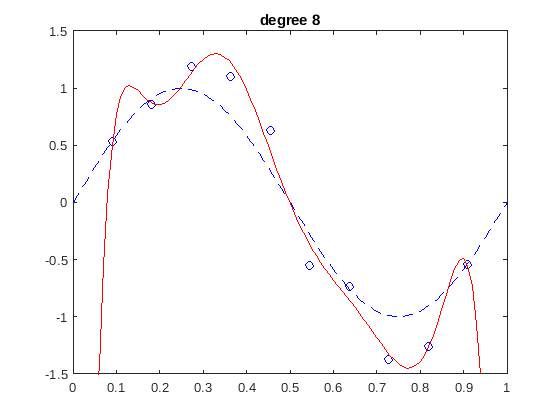

for deg = 1:9
  % compute the polynomial weights
  X = X0(:,1:deg+1);
  w = X\y;
  % compute the polynomial at values of xx
  xx = (0:.01:1)';
  yy = w(1)*ones(size(xx));
  for k = 1:deg
    yy = yy + w(k+1)*(xx.^k);
  end
  % plot the true function, the data, and the polynomial
  figure
  plot(xx,fun(xx),'b--', x,y,'bo', xx,yy,'r-');
  title(sprintf('degree %d', deg))
  axis([0 1 -1.5 1.5]);
end

What degree polynomial seems to best fit the data?

Polynomial regression is not used in practice, because of the large fluctuations in the polynomial when the polynomial degree increases and the polynomial starts to overfit the data. We will see later that polynomial regression with regularization can help avoid overfitting the data and will work much better.